# Test: Square Root Unscented Kalman Filter

## Simple Validation

Setting RNG:

rng(420)

Setting sample state transiton function:

f = @(x,v,u) x+v+u;
h = @(x,n) x;
x0 = [5 10]';

The noise variance passed to the filter (normally taken from datasheet/experiment). It is intentionally not the exact variance of $x_{true}-y$.

varN = 5;
varX = 1;
varV = 1;

Create instance of UKF class:

ukf1 = spkf.SquareRootUnscentedKalmanFilter(f,h,x0,varX,varV,varN);
ukf1.SigmaPointsSelector.Alpha = 1E-3;
ukf1.SigmaPointsSelector.Beta = 2;
ukf1.SigmaPointsSelector.Kappa = 0;

Creating an instance of the Mathworks version for comparison:

ukf2 = unscentedKalmanFilter( ...
    'HasAdditiveProcessNoise', false, ...
    'HasAdditiveMeasurementNoise', false);
ukf2.StateCovariance = varX;
ukf2.StateTransitionFcn = f;
ukf2.MeasurementFcn = h;
ukf2.State = x0;
ukf2.ProcessNoise = varV;
ukf2.MeasurementNoise = varN;

The results of both filters should fall in the same tolerance range:

tolerance = 1E-2;

Number of prediction steps:

steps = 20;

Generating a control sequence $u$:

u = zeros(1,steps);
u(:) = 5;

A true state is defined for comparison:

x_true = zeros(size(x0,1),steps);

The starting point is different from the point $x0$ passed to the ukfs.

x_true(:,1) = [1 1]';

Generating measurement data.

y = zeros(size(x0,1),steps);
for i=2:steps
    x_true(:,i) = f(x_true(:,i-1),0,u(:,i-1));
    y(:,i) = x_true(:,i)*(1+randi([-10 10])/100);
end

Prediction AND Correction steps:

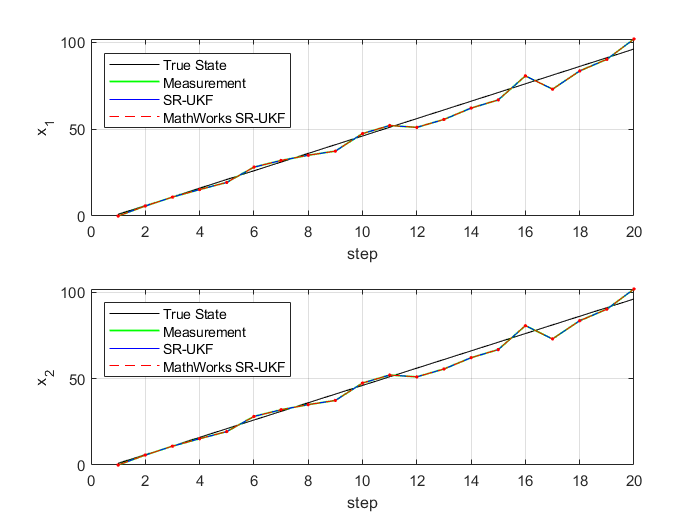

x1_pred = zeros(size(x0,1),steps);
x1_corr = zeros(size(x0,1),steps);
c1_pred = zeros(size(x0,1),size(x0,1),steps);
c1_corr = zeros(size(x0,1),size(x0,1),steps);

x2_pred = zeros(size(x0,1),steps);
c2_pred = zeros(size(x0,1),size(x0,1),steps);
x2_corr = zeros(size(x0,1),steps);
c2_corr = zeros(size(x0,1),size(x0,1),steps);

for i=1:steps
    [x1_pred(:,i), c1_pred(:,:,i)] = ukf1.predict(u(:,i));
    [x1_corr(:,i), c1_corr(:,:,i)] = ukf1.correct(y(:,i));
    [x2_pred(:,i), c2_pred(:,:,i)] = ukf2.predict(u(:,i));
    [x2_corr(:,i), c2_corr(:,:,i)] = ukf2.correct(y(:,i));
end

tiledlayout(2,1)

nexttile
plot(1:steps,x_true(1,:),'Color','k'); hold on
plot(1:steps,y(1,:),'Color','g','LineWidth',1)
plot(1:steps,x1_corr(1,:),'Color','b')
plot(1:steps,x2_corr(1,:),'--','Color','r')
plot(1:steps,x1_corr(1,:),'.','Color','b')
plot(1:steps,x2_corr(1,:),'.','Color','r')
xlabel("step"); ylabel("x_1")
legend("True State", "Measurement", "SR-UKF", "MathWorks SR-UKF", "Location", "northwest")
grid on

nexttile
plot(1:steps,x_true(2,:),'Color','k'); hold on
plot(1:steps,y(1,:),'Color','g','LineWidth',1)
plot(1:steps,x1_corr(2,:),'Color','b')
plot(1:steps,x2_corr(2,:),'--','Color','r')
plot(1:steps,x1_corr(2,:),'.','Color','b')
plot(1:steps,x2_corr(2,:),'.','Color','r')
xlabel("step"); ylabel("x_2")
legend("True State", "Measurement", "SR-UKF", "MathWorks SR-UKF", "Location", "northwest")
grid on


assert(all(abs(x1_corr)-abs(x2_corr)<tolerance,'all'),...
    'Large difference in state estimate')
assert(all(abs(c1_corr)-abs(c2_corr)<tolerance,'all'),...
    'Large difference in state error covariance')

## More Complex Validation

Set RNG:

rng(420)

Set functions and initial state:

f = @vdpStateFcnCustom;
h = @vdpMeasurementNonAdditiveNoiseFcn;
x0 = [0 0]';

The noise variance passed to the filter (normally taken from datasheet/experiment). It is intentionally not the exact variance of $x_{true}-y$.

varN = 0.2;
varV = diag([0.02 0.1]);

Create instance of UKF class:

ukf1 = spkf.SquareRootUnscentedKalmanFilter(f,h,x0,[],varV,varN);
ukf1.SigmaPointsSelector.Alpha = 1E-3;
ukf1.SigmaPointsSelector.Beta = 2;
ukf1.SigmaPointsSelector.Kappa = 0;

Creating an instance of the Mathworks version for comparison:

ukf2 = unscentedKalmanFilter( ...
    'HasAdditiveProcessNoise', false, ...
    'HasAdditiveMeasurementNoise', false);
ukf2.StateTransitionFcn = f;
ukf2.MeasurementFcn = h;
ukf2.State = x0;
ukf2.ProcessNoise = varV;
ukf2.MeasurementNoise = varN;

The results of both filters should fall in the same tolerance range:

tolerance = 1E-2;

Generating true data:

T = 0.05; % [s] Filter sample time
timeVector = 0:T:5;
[~,x_true]=ode45(@vdp1,timeVector,[2; 0]);
x_true = x_true';
y_true = x_true(1,:);
y = y_true .* (1+sqrt(varN)*randn(size(y_true))); % sqrt(R): Standard deviation of noise

Number of steps:

steps = numel(y_true);

Prediction / Correction steps:

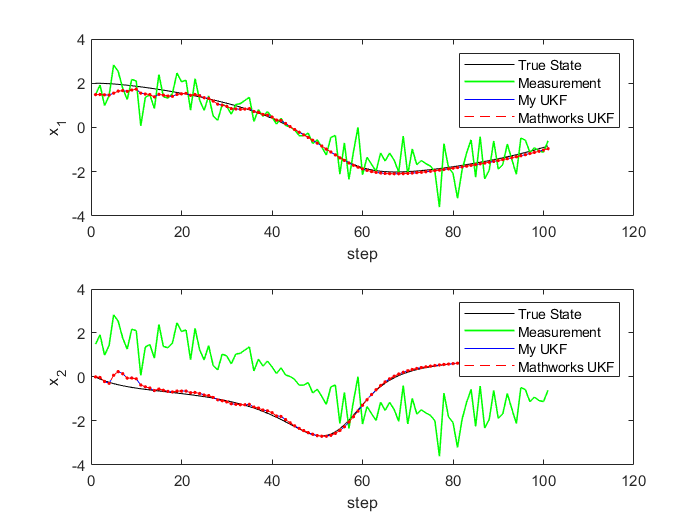

x1_pred = zeros(size(x0,1),steps);
x1_corr = zeros(size(x0,1),steps);
c1_pred = zeros(size(x0,1),size(x0,1),steps);
c1_corr = zeros(size(x0,1),size(x0,1),steps);

x2_pred = zeros(size(x0,1),steps);
c2_pred = zeros(size(x0,1),size(x0,1),steps);
x2_corr = zeros(size(x0,1),steps);
c2_corr = zeros(size(x0,1),size(x0,1),steps);

for i=1:steps
    [x1_pred(:,i), c1_pred(:,:,i)] = ukf1.predict();
    [x1_corr(:,i), c1_corr(:,:,i)] = ukf1.correct(y(:,i));
    [x2_pred(:,i), c2_pred(:,:,i)] = ukf2.predict();
    [x2_corr(:,i), c2_corr(:,:,i)] = ukf2.correct(y(:,i));
end

tiledlayout(2,1)

nexttile
plot(1:steps,x_true(1,:),'Color','k'); hold on
plot(1:steps,y(1,:),'Color','g','LineWidth',1)
plot(1:steps,x1_corr(1,:),'Color','b')
plot(1:steps,x2_corr(1,:),'--','Color','r')
plot(1:steps,x1_corr(1,:),'.','Color','b')
plot(1:steps,x2_corr(1,:),'.','Color','r')
xlabel("step"); ylabel("x_1")
legend("True State", "Measurement", "My UKF", "Mathworks UKF")

nexttile
plot(1:steps,x_true(2,:),'Color','k'); hold on
plot(1:steps,y(1,:),'Color','g','LineWidth',1)
plot(1:steps,x1_corr(2,:),'Color','b')
plot(1:steps,x2_corr(2,:),'--','Color','r')
plot(1:steps,x1_corr(2,:),'.','Color','b')
plot(1:steps,x2_corr(2,:),'.','Color','r')
xlabel("step"); ylabel("x_2")
legend("True State", "Measurement", "My UKF", "Mathworks UKF")

assert(all(abs(x1_corr)-abs(x2_corr)<tolerance,'all'),...
    'Large difference in state estimate')
assert(all(abs(c1_corr)-abs(c2_corr)<tolerance,'all'),...
    'Large difference in state error covariance')

## Testing Robustness

## More Complex Validation

Set RNG:

rng(420)

Set functions and initial state:

f = @vdpStateFcnCustom;
h = @vdpMeasurementNonAdditiveNoiseFcn;
x0 = [0 0]';

The noise variance passed to the filter (normally taken from datasheet/experiment). It is intentionally not the exact variance of $x_{true}-y$.

varN = 0.2;
varV = diag([0.02 0.1]);

Create instance of UKF class:

ukf1 = spkf.SquareRootUnscentedKalmanFilter(f,h,x0,[],varV,varN);
ukf1.SigmaPointsSelector.Alpha = 1E-3;
ukf1.SigmaPointsSelector.Beta = 2;
ukf1.SigmaPointsSelector.Kappa = 0;

Creating an instance of the Mathworks version for comparison:

ukf2 = unscentedKalmanFilter( ...
    'HasAdditiveProcessNoise', false, ...
    'HasAdditiveMeasurementNoise', false);
ukf2.StateTransitionFcn = f;
ukf2.MeasurementFcn = h;
ukf2.State = x0;
ukf2.ProcessNoise = varV;
ukf2.MeasurementNoise = varN;

The results of both filters should fall in the same tolerance range:

tolerance = 1E-2;

Generating true data:

T = 0.05; % [s] Filter sample time
timeVector = 0:T:100;
[~,x_true]=ode45(@vdp1,timeVector,[2; 0]);
x_true = x_true';
y_true = x_true(1,:);
% y = y_true .* (1+sqrt(varN)*randn(size(y_true))); % sqrt(R): Standard deviation of noise
y = ones(size(y_true));

Number of steps:

steps = numel(y_true);

Prediction / Correction steps:

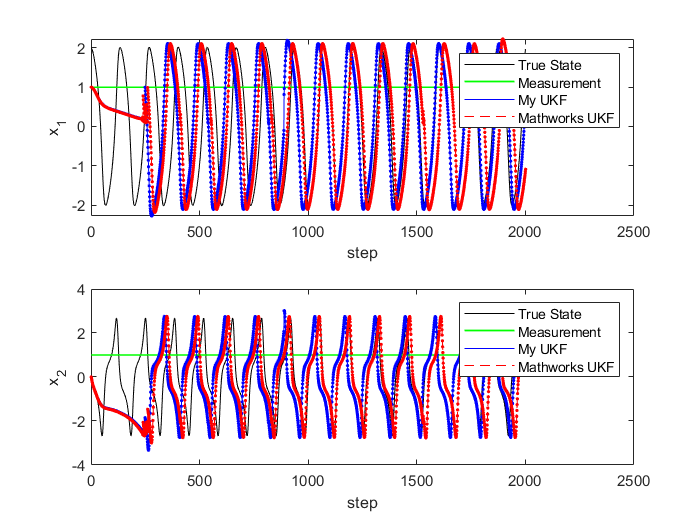

x1_pred = zeros(size(x0,1),steps);
x1_corr = zeros(size(x0,1),steps);
c1_pred = zeros(size(x0,1),size(x0,1),steps);
c1_corr = zeros(size(x0,1),size(x0,1),steps);

x2_pred = zeros(size(x0,1),steps);
c2_pred = zeros(size(x0,1),size(x0,1),steps);
x2_corr = zeros(size(x0,1),steps);
c2_corr = zeros(size(x0,1),size(x0,1),steps);

for i=1:steps
    [x1_pred(:,i), c1_pred(:,:,i)] = ukf1.predict();
    [x1_corr(:,i), c1_corr(:,:,i)] = ukf1.correct(y(:,i));
    [x2_pred(:,i), c2_pred(:,:,i)] = ukf2.predict();
    [x2_corr(:,i), c2_corr(:,:,i)] = ukf2.correct(y(:,i));
end

tiledlayout(2,1)

nexttile
plot(1:steps,x_true(1,:),'Color','k'); hold on
plot(1:steps,y(1,:),'Color','g','LineWidth',1)
plot(1:steps,x1_corr(1,:),'Color','b')
plot(1:steps,x2_corr(1,:),'--','Color','r')
plot(1:steps,x1_corr(1,:),'.','Color','b')
plot(1:steps,x2_corr(1,:),'.','Color','r')
xlabel("step"); ylabel("x_1")
legend("True State", "Measurement", "My UKF", "Mathworks UKF")

nexttile
plot(1:steps,x_true(2,:),'Color','k'); hold on
plot(1:steps,y(1,:),'Color','g','LineWidth',1)
plot(1:steps,x1_corr(2,:),'Color','b')
plot(1:steps,x2_corr(2,:),'--','Color','r')
plot(1:steps,x1_corr(2,:),'.','Color','b')
plot(1:steps,x2_corr(2,:),'.','Color','r')
xlabel("step"); ylabel("x_2")
legend("True State", "Measurement", "My UKF", "Mathworks UKF")